% EDIT THESE TO PLAY: 

% Where to save: 
outFolder = [userFolder filesep 'toolboxes' filesep 'qpfmri' filesep 'tests' filesep 'Results'];

% Set the seed to have repeatable control.
seed = 123;

% You can also add in simulation params here. 
% Param1 = exponent
% Param2 = semiSat
% Param3 = beta (keep this 1)
% Param4 = sigma (keep this .01, but you'll set noise below).
simulatedPsiParams = [];
%simulatedPsiParams = [.3162, .55, 1, .01];

% Noise in standard deviations of maxBOLD
noiseSD = .6;

% headroom
%headroom = 0;

% Number of trials to run.
nTrials = 20;

% Initial baseline and max BOLD trials.
% Max BOLD trials are not necessary with maxBOLD locked, but at least 1
% baseline is required.
baselineMaxBOLDInitial = 1;


% The following options can be edited, but probably don't make much
% difference.

% Provide a model handle
model = @nakaRushton;

% Specify the parameter domain. Each value must correspond to a parameter
% expected by the model. 
paramsDomain = struct;
paramsDomain.exponent = makeDomain(-1,1,15,'spacing','log');
paramsDomain.semiSat = makeDomain(.1,1,15);

% We are locking in beta right now. 
paramsDomain.beta = makeDomain(.75,1.25,1,'spacing','zeno');
% To enable maxBOLD, use this line and change the line below to something besides 1.5:
%paramsDomain.beta = makeDomain(.75,1.25,11,'spacing','zeno');
%maxBOLDInitialGuess = 1.5;

% Sigma in the parameter domain is searching for noiseSD
paramsDomain.sigma = makeDomain(0.01,1,20);

% Specify a stimulus domain and whether it spaced linear or log.
stimulusDomain = {makeDomain(.0001,1,15)};
stimulusDomainSpacing = 'lin';

% Set the number of outcome categories / bins.
nOutcomes = 21;

%How long the trials are (in seconds).
trialLength = 24;

% Do you want to see plots?
showPlots = true; 

% Again, important to lock in BOLD for the moment. 
% The range of BOLD signal to simulate (e.g., from baseline to maximum BOLD)
maxBOLDSimulated = 1.5;
maxBOLDInitialGuess = 1.5;



Initial random call 0.3813
Random call after seed 0.6965


Initializing Q+. This may take a minute...
Elapsed time is 0.464400 seconds.


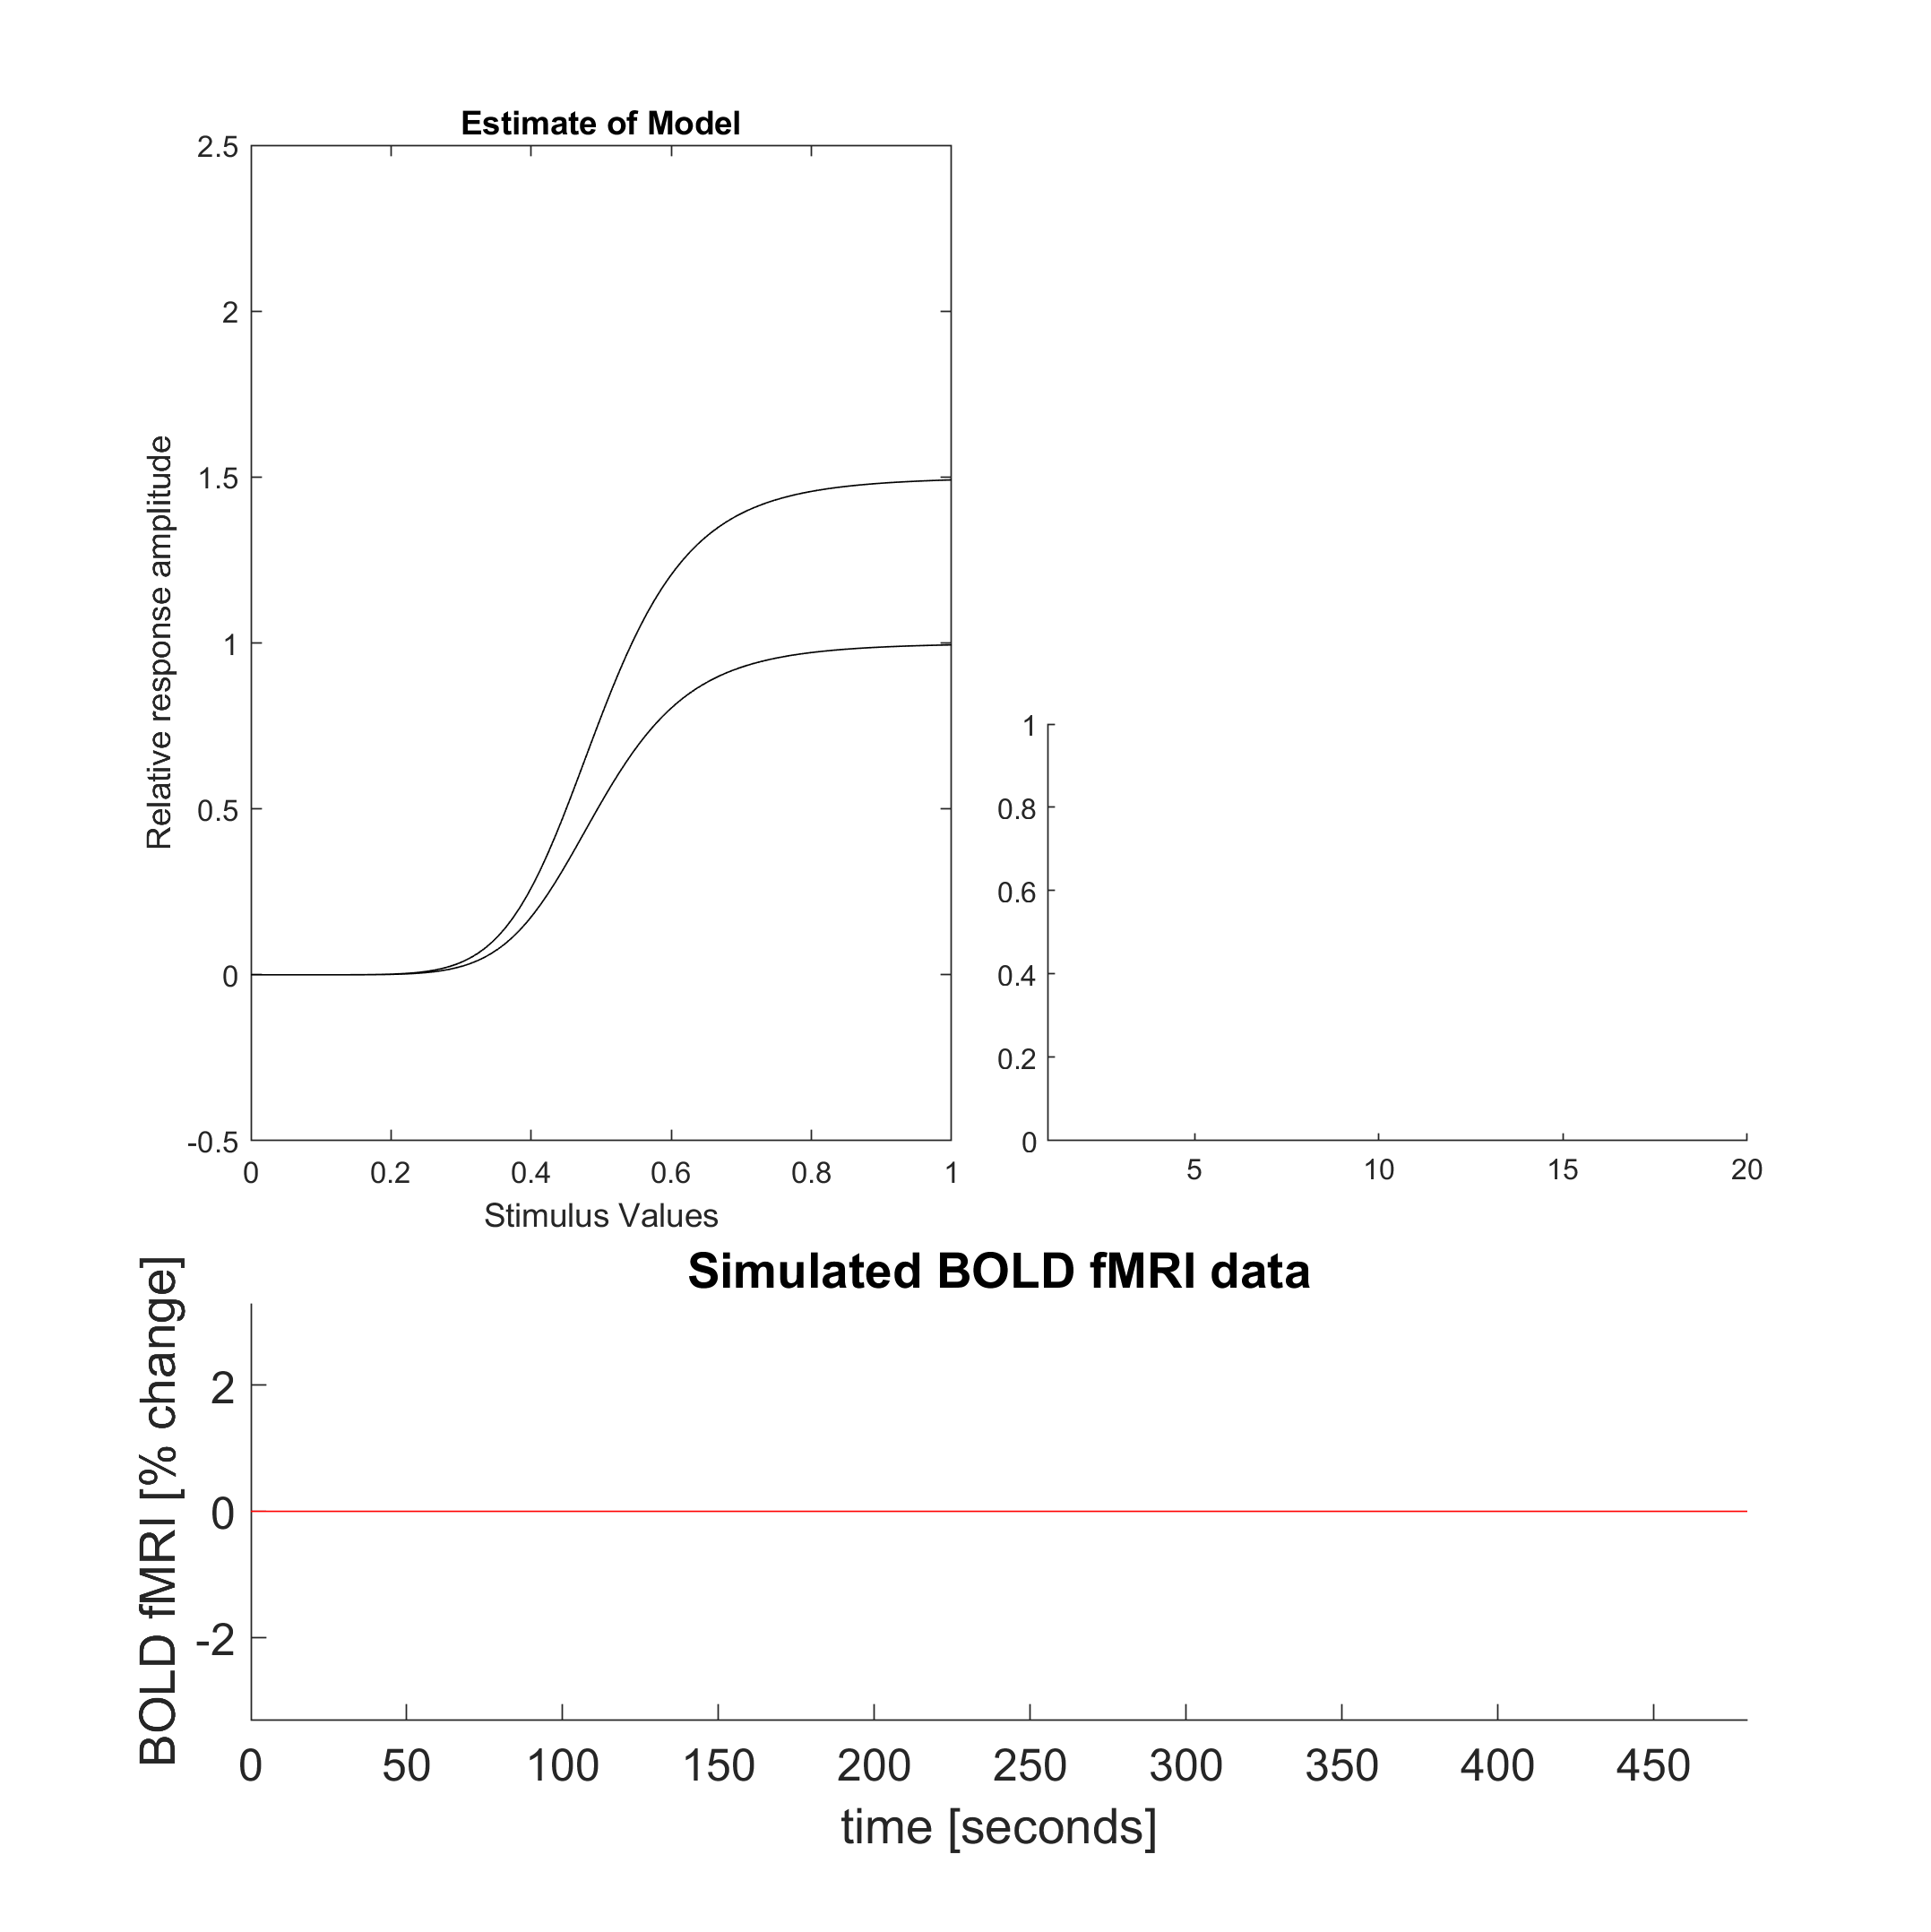

Simulated parameters:
exponent: 7.318 semiSat: 0.495 beta: 1.000 sigma: 0.600 
Noise in the simulation is set at 1.800 relative to a maxBOLD of 1.50



% Allow Q+ to control the stimuli or not (false).
qpPres = false;

date = datestr(now,'yyyymmddhhMMss');

% Save outNum based on values above
formatSpec = 'noise-%0.4f_qplus-%s_nOutcomes-%d_trials-%d_seed-%d_date-%s';
outNum = sprintf(formatSpec,noiseSD,num2str(qpPres),nOutcomes,nTrials,seed,date);

[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams,...,
'outFolder',outFolder,'outNum',outNum);


% Run the simulation for the first 'run'. 
[qpfmriResults,questDataFalse]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots,'saveFigs',true);

% Run the simulation again, providing the output from the first run. 
outNum = sprintf(formatSpec,noiseSD,num2str(qpPres),nOutcomes,nTrials,seed,date);

[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams,...,
'outFolder',outFolder,'outNum',outNum);

[qpfmriResults]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots,'saveFigs',true,'questData',questDataFalse);

Initial random call 0.5924
Random call after seed 0.8929


Initializing Q+. This may take a minute...
Elapsed time is 0.443605 seconds.


Simulated parameters:
exponent: 8.217 semiSat: 0.472 beta: 1.000 sigma: 0.600 
Noise in the simulation is set at 1.800 relative to a maxBOLD of 1.50

Trial 1: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 0.517 semiSat: 0.100 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 2: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.176

Q+ parameters
exponent: 2.684 semiSat: 0.872 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 3: qplus Stimulus Selection
Stimulus: 0.714
Output value 1.500

Q+ parameters
exponent: 9.948 semiSat: 0.554 beta: 1.000 sigma: 0.065 
maxBOLD estimate = 1.500




Trial 4: qplus Stimulus Selection
Stimulus: 0.214
Output value -0.176

Q+ parameters
exponent: 10.000 semiSat: 0.622 beta: 1.000 sigma: 0.061 
maxBOLD estimate = 1.500




Trial 5: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.147

Q+ parameters
exponent: 10.000 semiSat: 0.615 beta: 1.000 sigma: 0.114 
maxBOLD estimate = 1.500




Trial 6: qplus Stimulus Selection
Stimulus: 0.929
Output value 1.500

Q+ parameters
exponent: 10.000 semiSat: 0.612 beta: 1.000 sigma: 0.106 
maxBOLD estimate = 1.500




Trial 7: qplus Stimulus Selection
Stimulus: 0.643
Output value 0.971

Q+ parameters
exponent: 10.000 semiSat: 0.611 beta: 1.000 sigma: 0.095 
maxBOLD estimate = 1.500




Trial 8: qplus Stimulus Selection
Stimulus: 0.571
Output value 1.059

Q+ parameters
exponent: 9.988 semiSat: 0.531 beta: 1.000 sigma: 0.104 
maxBOLD estimate = 1.500




Trial 9: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.618

Q+ parameters
exponent: 8.822 semiSat: 0.512 beta: 1.000 sigma: 0.131 
maxBOLD estimate = 1.500




Trial 10: baseline Stimulus Selection
Stimulus: 0.000
Output value -0.176

Q+ parameters
exponent: 8.878 semiSat: 0.474 beta: 1.000 sigma: 0.120 
maxBOLD estimate = 1.500




Trial 11: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.265

Q+ parameters
exponent: 7.647 semiSat: 0.497 beta: 1.000 sigma: 0.109 
maxBOLD estimate = 1.500




Trial 12: qplus Stimulus Selection
Stimulus: 0.571
Output value 1.147

Q+ parameters
exponent: 8.017 semiSat: 0.495 beta: 1.000 sigma: 0.103 
maxBOLD estimate = 1.500




Trial 13: qplus Stimulus Selection
Stimulus: 0.571
Output value 1.059

Q+ parameters
exponent: 6.336 semiSat: 0.500 beta: 1.000 sigma: 0.104 
maxBOLD estimate = 1.500




Trial 14: qplus Stimulus Selection
Stimulus: 0.571
Output value 1.588

Q+ parameters
exponent: 7.627 semiSat: 0.484 beta: 1.000 sigma: 0.137 
maxBOLD estimate = 1.500




Trial 15: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.147

Q+ parameters
exponent: 7.581 semiSat: 0.483 beta: 1.000 sigma: 0.144 
maxBOLD estimate = 1.500




Trial 16: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.882

Q+ parameters
exponent: 6.095 semiSat: 0.472 beta: 1.000 sigma: 0.142 
maxBOLD estimate = 1.500




Trial 17: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.088

Q+ parameters
exponent: 7.663 semiSat: 0.484 beta: 1.000 sigma: 0.150 
maxBOLD estimate = 1.500




Trial 18: qplus Stimulus Selection
Stimulus: 0.429
Output value -0.176

Q+ parameters
exponent: 8.864 semiSat: 0.493 beta: 1.000 sigma: 0.166 
maxBOLD estimate = 1.500




Trial 19: qplus Stimulus Selection
Stimulus: 0.571
Output value 1.588

Q+ parameters
exponent: 10.000 semiSat: 0.477 beta: 1.000 sigma: 0.166 
maxBOLD estimate = 1.500




Trial 20: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 10.000 semiSat: 0.470 beta: 1.000 sigma: 0.159 
maxBOLD estimate = 1.500



--------------------------------------------------------------
FINAL VALUES
--------------------------------------------------------------
Simulated parameters:              exponent: 8.217 semiSat: 0.472 beta: 1.000 sigma: 0.600 
Max posterior QUEST+ parameters:   exponent: 10.000 semiSat: 0.486 beta: 1.000 sigma: 0.166 
Max BADS parameters:               exponent: 10.000 semiSat: 0.468 beta: 1.000 sigma: 0.159 
maxBOLD estimate: 1.500


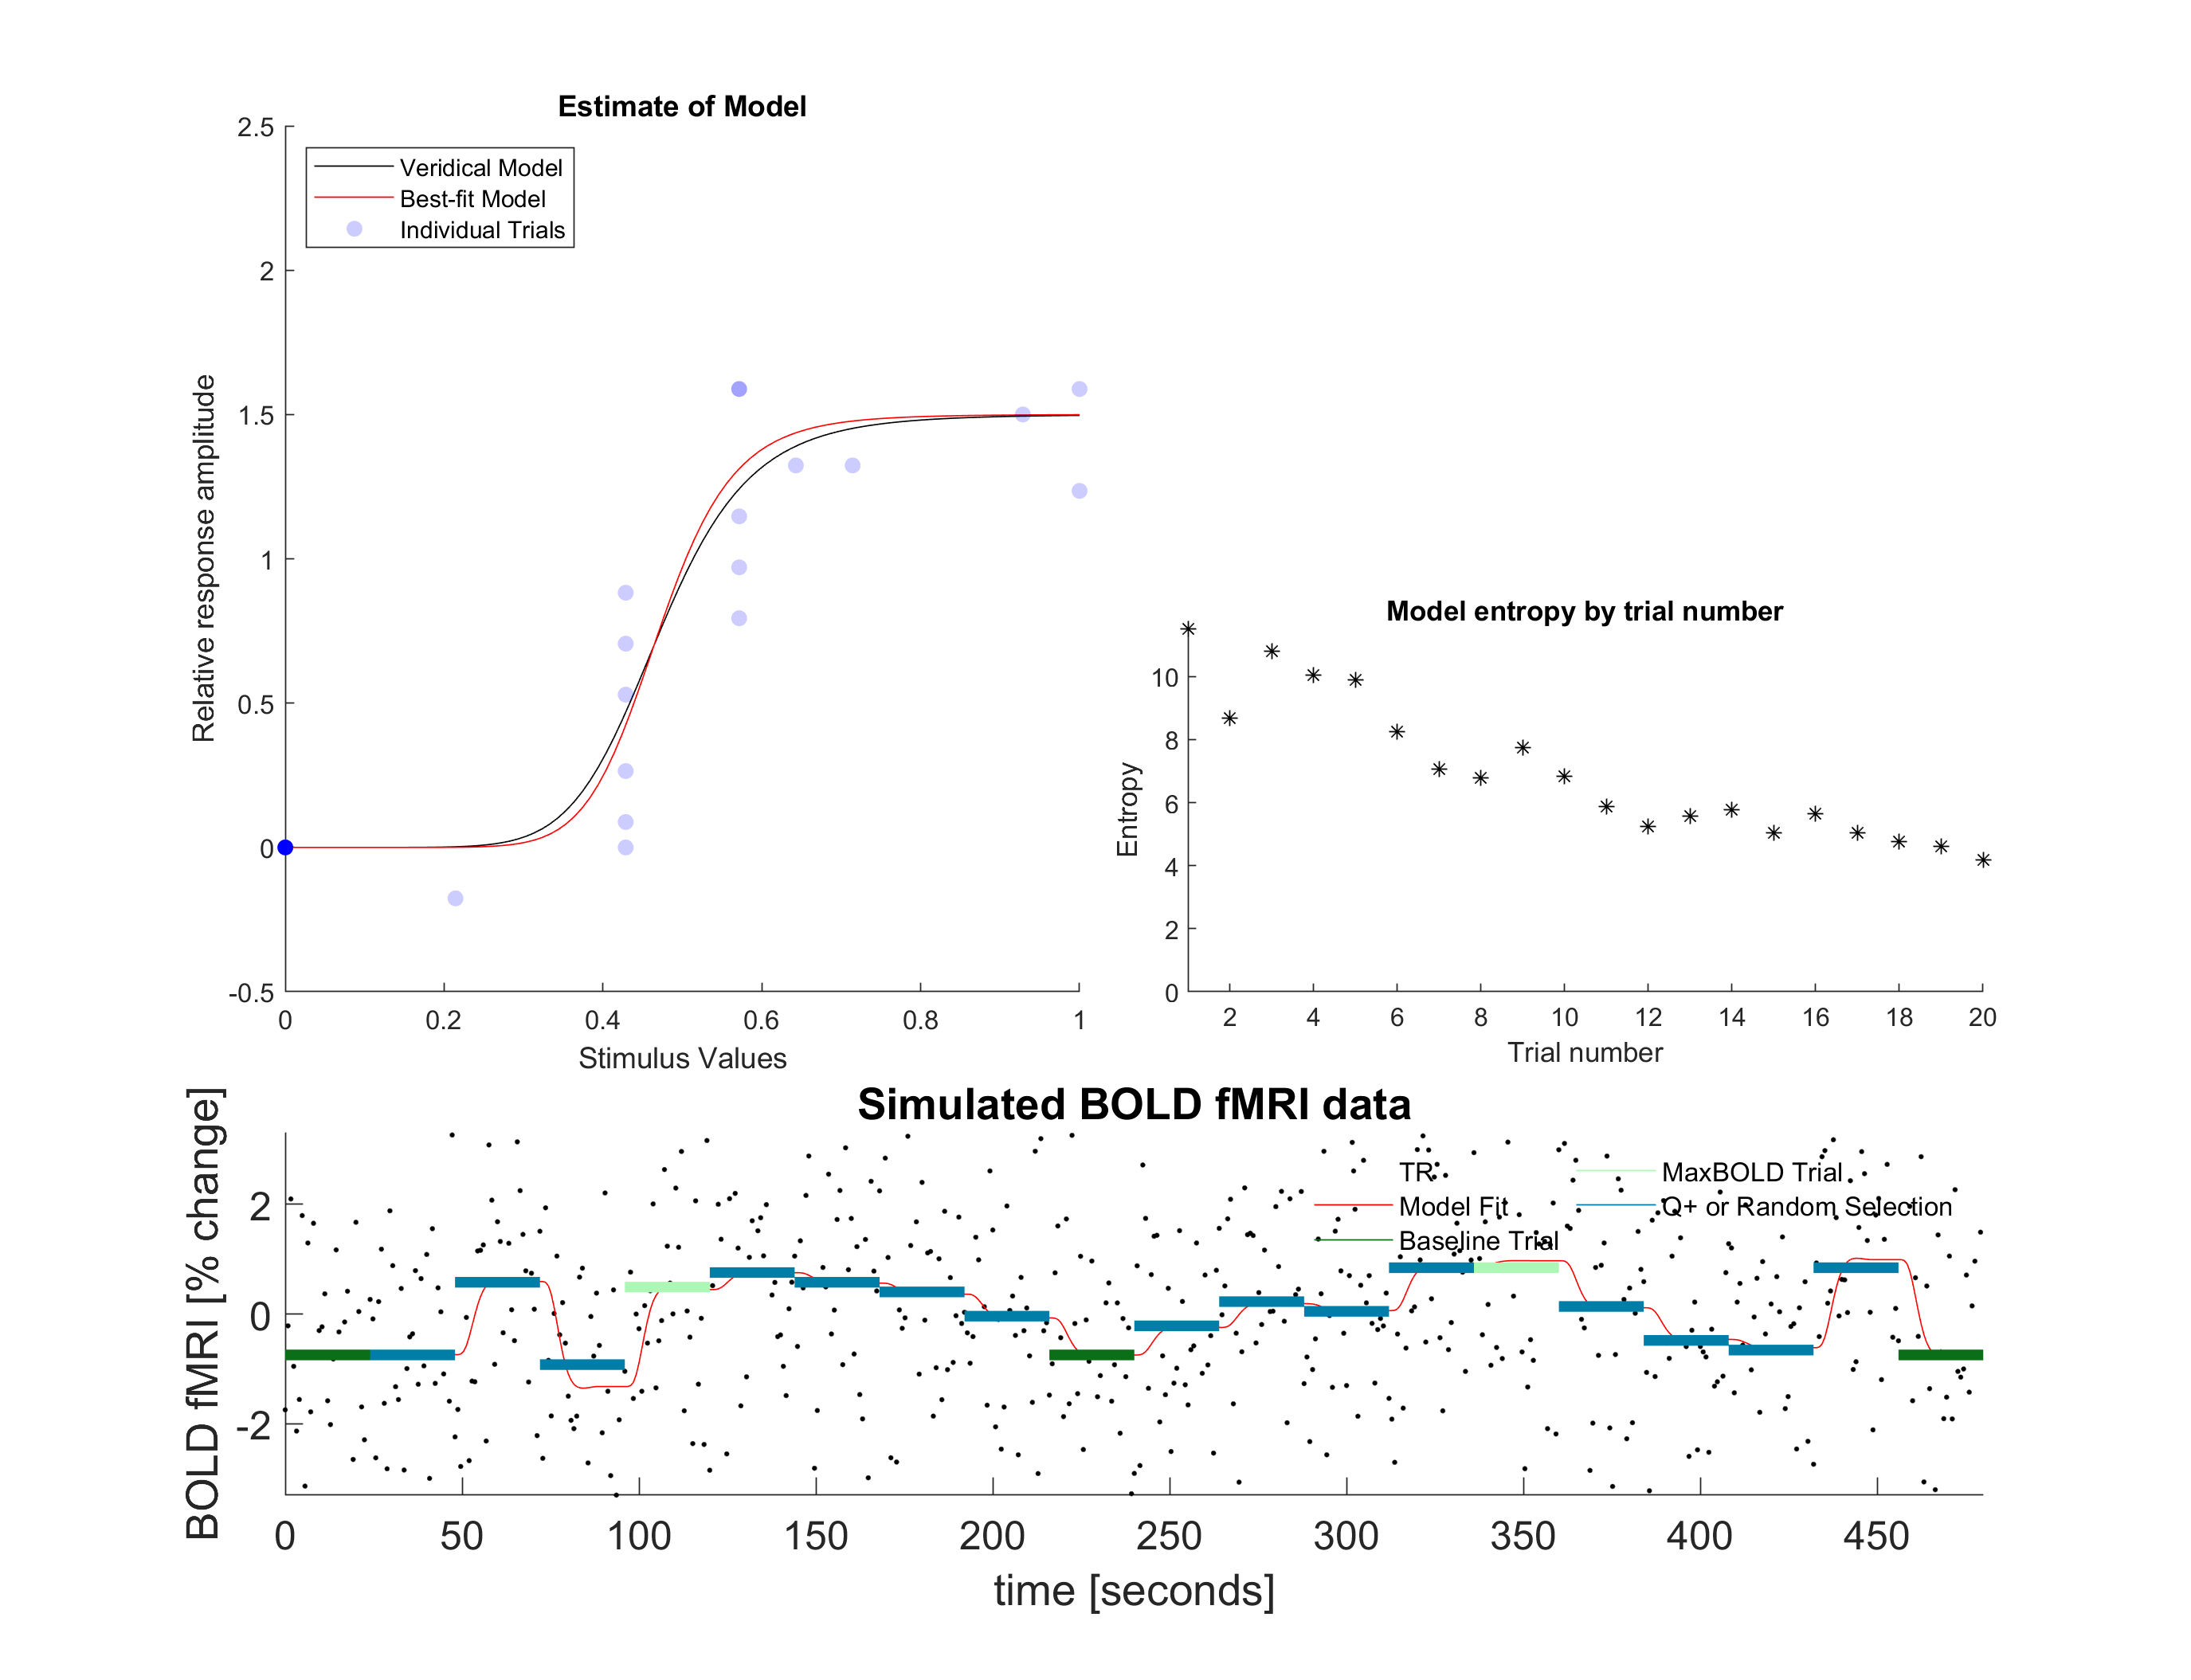

% Allow Q+ to control the stimuli or not (false).
qpPres = true;


% Save outNum based on values above
formatSpec = 'noise-%0.4f_qplus-%s_nOutcomes-%d_trials-%d_seed-%d_date-%s';
outNum = sprintf(formatSpec,noiseSD,num2str(qpPres),nOutcomes,nTrials,seed,date);

[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams,...,
'outFolder',outFolder,'outNum',outNum);


% Run the simulation. 
[qpfmriResults,questDataQp]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots,'saveFigs',true);

Initial random call 0.3815
Random call after seed 0.8929


Simulated parameters:
exponent: 8.217 semiSat: 0.472 beta: 1.000 sigma: 0.600 
Noise in the simulation is set at 1.800 relative to a maxBOLD of 1.50

Trial 1: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 2.409 semiSat: 0.183 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 2: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.176

Q+ parameters
exponent: 3.320 semiSat: 0.765 beta: 1.000 sigma: 0.010 
maxBOLD estimate = 1.500




Trial 3: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.971

Q+ parameters
exponent: 9.965 semiSat: 0.495 beta: 1.000 sigma: 0.133 
maxBOLD estimate = 1.500




Trial 4: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.265

Q+ parameters
exponent: 9.621 semiSat: 0.802 beta: 1.000 sigma: 0.381 
maxBOLD estimate = 1.500




Trial 5: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.147

Q+ parameters
exponent: 9.479 semiSat: 0.708 beta: 1.000 sigma: 0.248 
maxBOLD estimate = 1.500




Trial 6: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.971

Q+ parameters
exponent: 9.507 semiSat: 0.654 beta: 1.000 sigma: 1.000 
maxBOLD estimate = 1.500




Trial 7: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.529

Q+ parameters
exponent: 10.000 semiSat: 0.759 beta: 1.000 sigma: 1.000 
maxBOLD estimate = 1.500




Trial 8: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.706

Q+ parameters
exponent: 9.992 semiSat: 0.512 beta: 1.000 sigma: 0.133 
maxBOLD estimate = 1.500




Trial 9: qplus Stimulus Selection
Stimulus: 0.500
Output value 1.059

Q+ parameters
exponent: 9.492 semiSat: 0.499 beta: 1.000 sigma: 0.147 
maxBOLD estimate = 1.500




Trial 10: baseline Stimulus Selection
Stimulus: 0.000
Output value -0.176

Q+ parameters
exponent: 10.000 semiSat: 0.481 beta: 1.000 sigma: 0.140 
maxBOLD estimate = 1.500




Trial 11: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.265

Q+ parameters
exponent: 9.995 semiSat: 0.492 beta: 1.000 sigma: 0.138 
maxBOLD estimate = 1.500




Trial 12: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.882

Q+ parameters
exponent: 10.000 semiSat: 0.495 beta: 1.000 sigma: 0.129 
maxBOLD estimate = 1.500




Trial 13: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.353

Q+ parameters
exponent: 10.000 semiSat: 0.496 beta: 1.000 sigma: 0.127 
maxBOLD estimate = 1.500




Trial 14: qplus Stimulus Selection
Stimulus: 0.500
Output value 1.500

Q+ parameters
exponent: 9.983 semiSat: 0.496 beta: 1.000 sigma: 0.171 
maxBOLD estimate = 1.500




Trial 15: maxBOLD Stimulus Selection
Stimulus: 1.000
Output value 1.147

Q+ parameters
exponent: 10.000 semiSat: 0.492 beta: 1.000 sigma: 0.158 
maxBOLD estimate = 1.500




Trial 16: qplus Stimulus Selection
Stimulus: 0.500
Output value 1.324

Q+ parameters
exponent: 10.000 semiSat: 0.482 beta: 1.000 sigma: 0.166 
maxBOLD estimate = 1.500




Trial 17: qplus Stimulus Selection
Stimulus: 0.429
Output value 0.088

Q+ parameters
exponent: 9.977 semiSat: 0.494 beta: 1.000 sigma: 0.163 
maxBOLD estimate = 1.500




Trial 18: qplus Stimulus Selection
Stimulus: 0.500
Output value 0.176

Q+ parameters
exponent: 10.000 semiSat: 0.495 beta: 1.000 sigma: 0.181 
maxBOLD estimate = 1.500




Trial 19: qplus Stimulus Selection
Stimulus: 0.500
Output value 1.500

Q+ parameters
exponent: 9.686 semiSat: 0.485 beta: 1.000 sigma: 0.181 
maxBOLD estimate = 1.500




Trial 20: baseline Stimulus Selection
Stimulus: 0.000
Output value 0.000

Q+ parameters
exponent: 9.955 semiSat: 0.480 beta: 1.000 sigma: 0.170 
maxBOLD estimate = 1.500



--------------------------------------------------------------
FINAL VALUES
--------------------------------------------------------------
Simulated parameters:              exponent: 8.217 semiSat: 0.472 beta: 1.000 sigma: 0.600 
Max posterior QUEST+ parameters:   exponent: 10.000 semiSat: 0.486 beta: 1.000 sigma: 0.166 
Max BADS parameters:               exponent: 10.000 semiSat: 0.484 beta: 1.000 sigma: 0.170 
maxBOLD estimate: 1.500


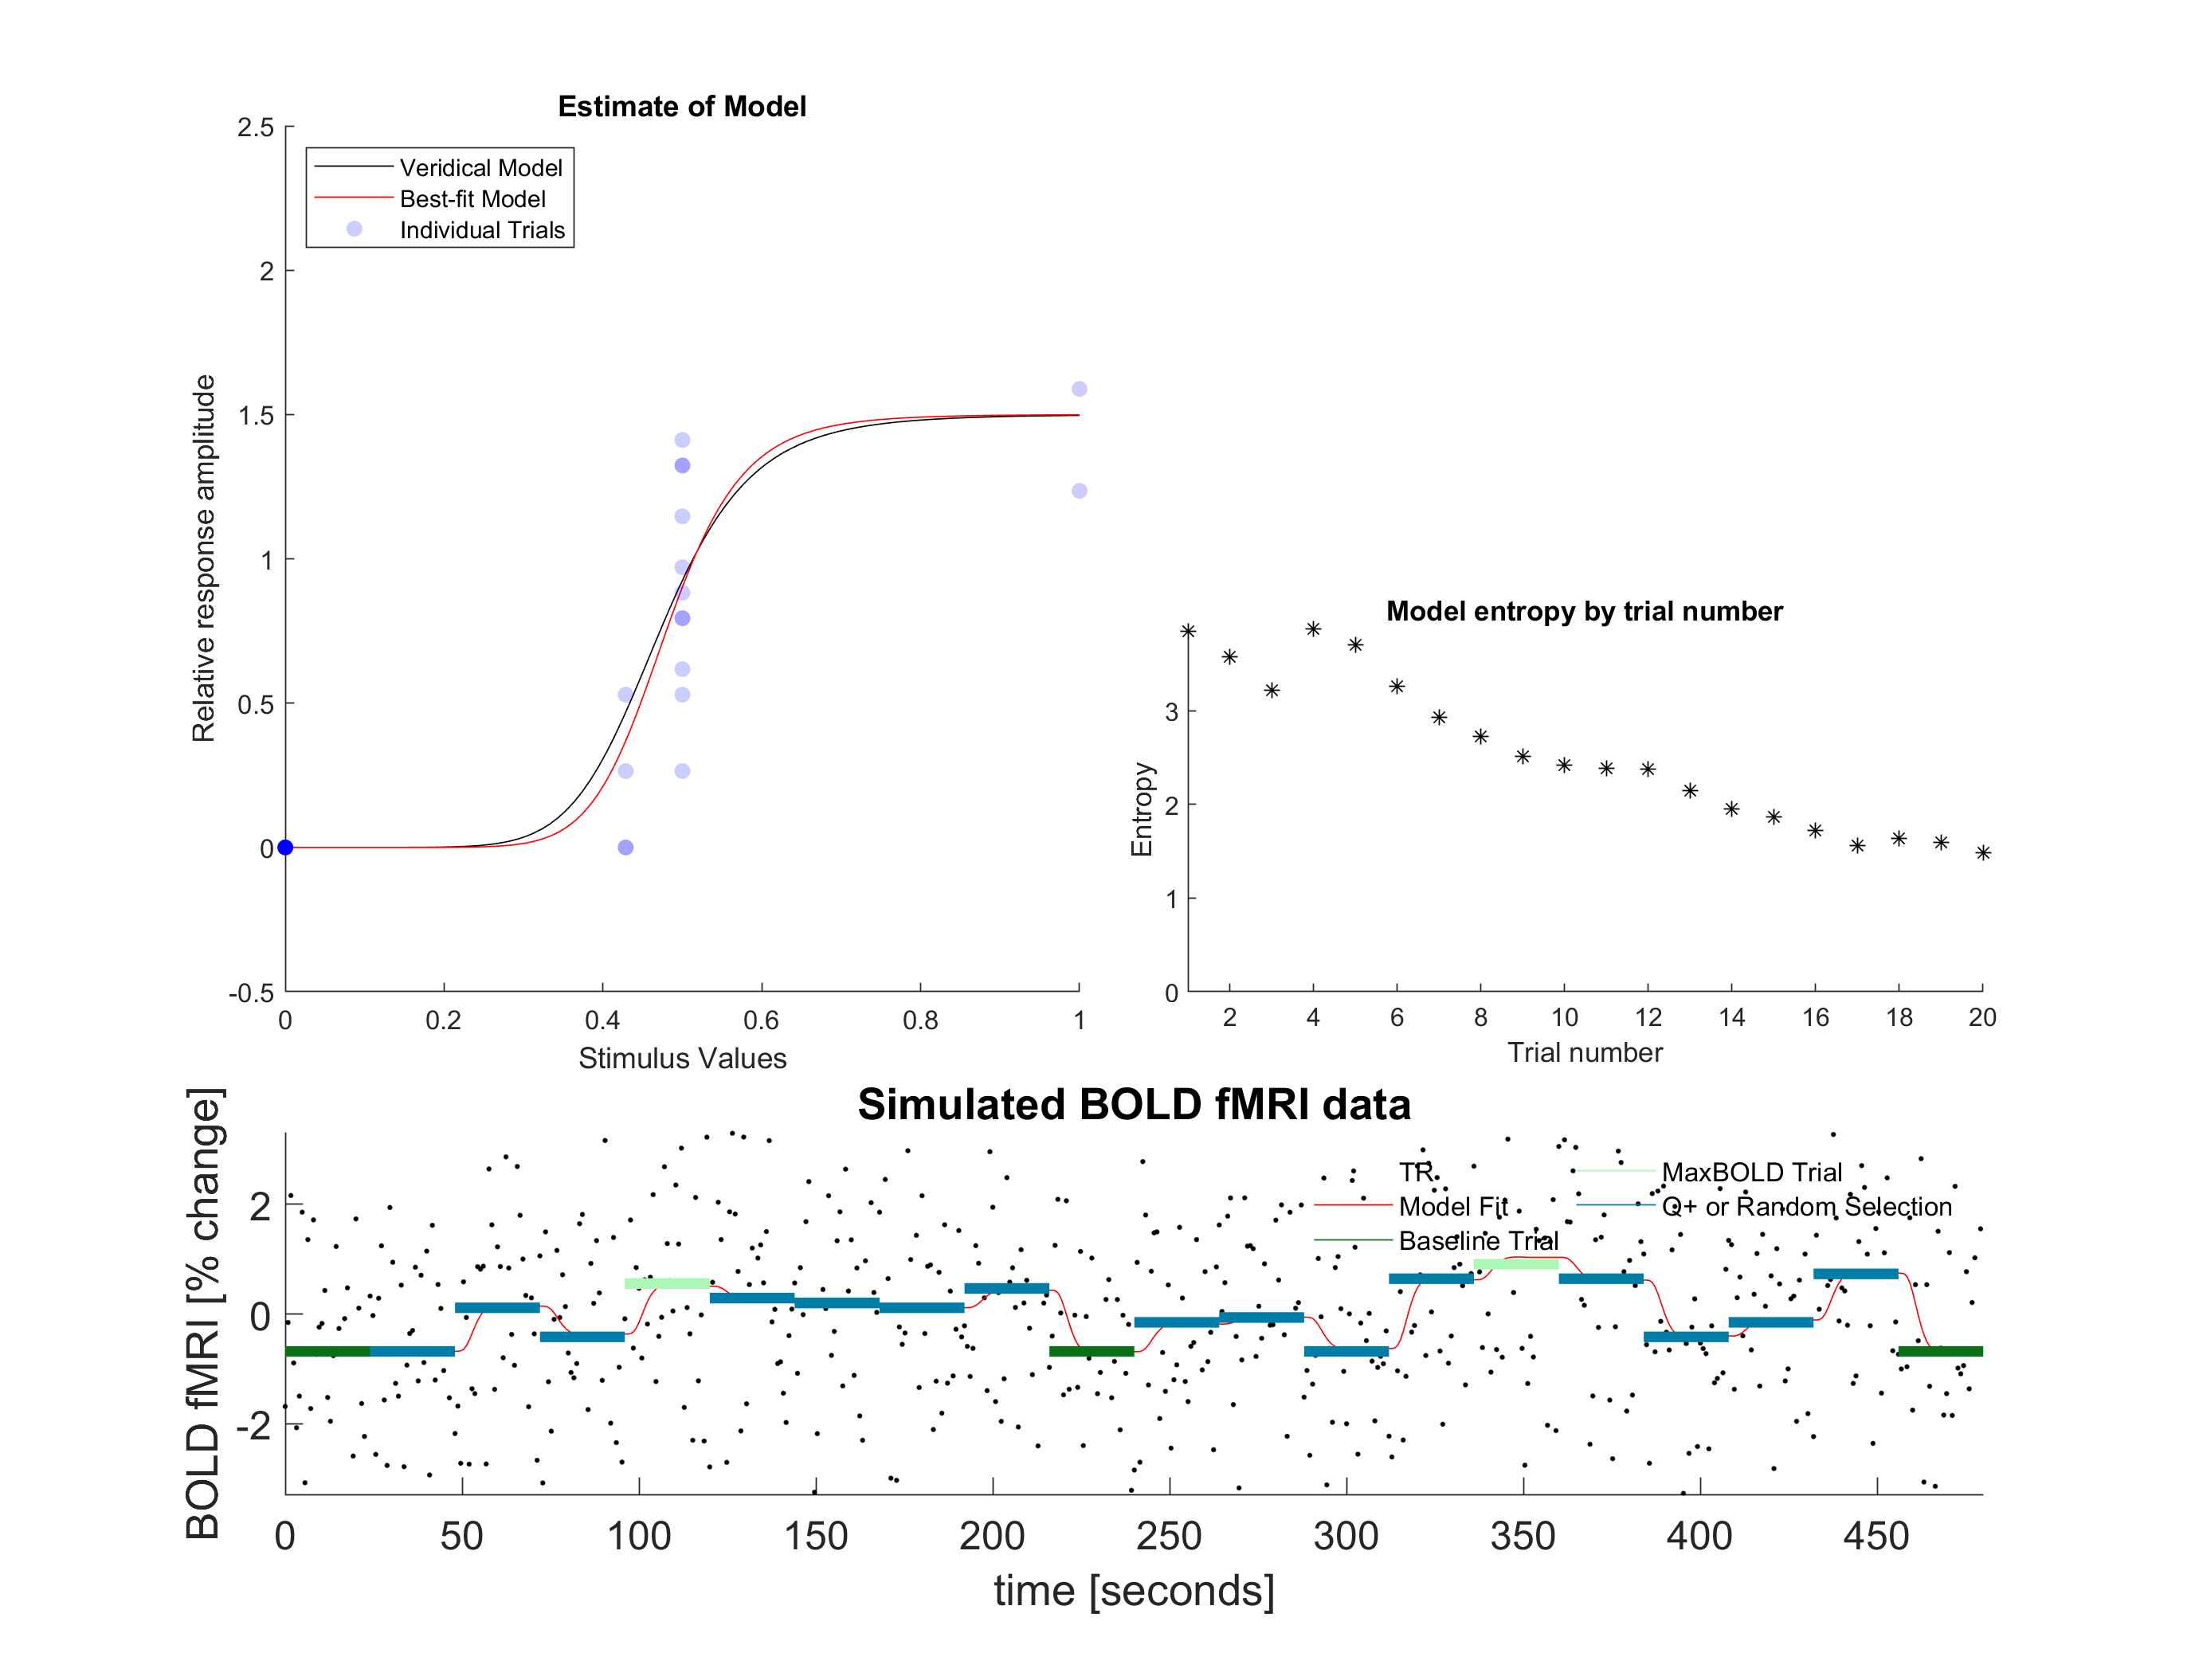

outNum = sprintf(formatSpec,noiseSD,num2str(qpPres),nOutcomes,nTrials,seed,date);

[myQpfmriParams,myQpParams] = qpfmriParams(model,paramsDomain,'qpPres',qpPres,...,
'stimulusDomain',stimulusDomain,'stimulusDomainSpacing',stimulusDomainSpacing,...,
'noiseSD',noiseSD,'nTrials',nTrials,'maxBOLDSimulated',maxBOLDSimulated,...,
'maxBOLDInitialGuess',maxBOLDInitialGuess,'seed',seed,...,
'baselineMaxBOLDInitial',baselineMaxBOLDInitial,...,
'trialLength',trialLength,'nOutcomes',nOutcomes,'simulatedPsiParams',simulatedPsiParams,...,
'outFolder',outFolder,'outNum',outNum);


[qpfmriResults]=simulate(myQpfmriParams,myQpParams,'showPlots',showPlots,'saveFigs',true,'questData',questDataQp);

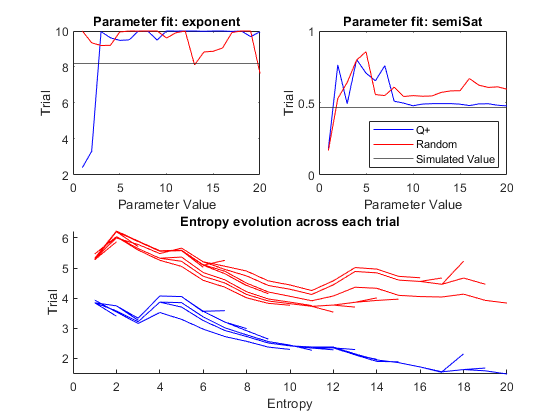

formatSpec = 'noise-%0.4f_qplus-%s_nOutcomes-%d_trials-%d_seed-%d_date-%s';

qpYesStem = sprintf(formatSpec,noiseSD,'1',nOutcomes,nTrials,seed,date);
qpYesResults = [outFolder filesep 'sim_' qpYesStem '.mat'];

qpNoStem = sprintf(formatSpec,noiseSD,'0',nOutcomes,nTrials,seed,date);
qpNoResults = [outFolder filesep 'sim_' qpNoStem '.mat'];


if isfile(qpYesResults) && isfile(qpNoResults)
    qpYes = load(qpYesResults);
    qpNo = load(qpNoResults);
end


% Extract Parameter names
paramNames = fieldnames(qpYes.qpfmriResults.paramsDomain);

% Create figure to show fits of parameters
outcomeFigure = figure; 

% Plot first parameter
subplot(2,2,1);
plot(qpYes.qpfmriResults.psiParamsBADS(:,1),'b'); 
hold on; 
plot(qpNo.qpfmriResults.psiParamsBADS(:,1),'r'); 
yline(qpYes.qpfmriResults.simulatedPsiParams(1)); 
title(sprintf('Parameter fit: %s',paramNames{1}));
xlabel('Parameter Value') 
ylabel('Trial') 

% Plot second parameter
subplot(2,2,2);
plot(qpYes.qpfmriResults.psiParamsBADS(:,2),'b'); 
hold on; 
plot(qpNo.qpfmriResults.psiParamsBADS(:,2),'r'); 
yline(qpYes.qpfmriResults.simulatedPsiParams(2)); 
title(sprintf('Parameter fit: %s',paramNames{2}));
legend('Q+','Random', 'Simulated Value','location','southeast');
xlabel('Parameter Value') 
ylabel('Trial') 


subplot(2,2,[3,4]);
hold on; 
for i = 1:length(qpYes.qpfmriResults.entropyOverTrials)
    plot(qpYes.qpfmriResults.entropyOverTrials{i},'b');
end
for i = 1:length(qpNo.qpfmriResults.entropyOverTrials)
    plot(qpNo.qpfmriResults.entropyOverTrials{i},'r');
end
title(sprintf('Entropy evolution across each trial'));
xlabel('Entropy') 
ylabel('Trial') 


set(outcomeFigure,'Units','Inches');
pos = get(outcomeFigure,'Position');
set(outcomeFigure,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)]);
print(outcomeFigure,fullfile(outFolder,[myQpfmriParams.outNum '_simulate_outcome.pdf']),'-dpdf','-r0');

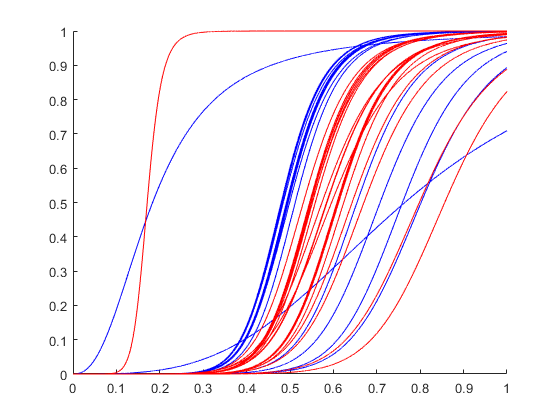

figure;
hold on; 

stimulusDomainFine = [min(cell2mat(qpYes.qpfmriResults.stimulusDomain)):.0001:max(cell2mat(qpYes.qpfmriResults.stimulusDomain))];

for i = 1:qpYes.qpfmriResults.nTrials
    plot(stimulusDomainFine,qpYes.qpfmriResults.model(stimulusDomainFine,qpYes.qpfmriResults.psiParamsBADS(i,:)),'-b');
end
for i = 1:qpNo.qpfmriResults.nTrials
    plot(stimulusDomainFine,qpNo.qpfmriResults.model(stimulusDomainFine,qpNo.qpfmriResults.psiParamsBADS(i,:)),'-r');
end